clear all; clc;

uetliberg = [47.351400190165414, 8.490228107569658];
ell = referenceEllipsoid('WGS84');

### Upsampling

% No Interp
load('/home/ygglc/desktop/phd/research/localization/core/localization-tdoa/matlab/sensys/zurich/mdphase_i1_c1_l1.mat')
dphase_1_1_0.lls = error_lls;
dphase_1_1_0.nlls = error_nlls;
[dphase_1_1_0.F_lls, dphase_1_1_0.X_lls] = ecdf(error_lls);
[dphase_1_1_0.F_nlls, dphase_1_1_0.X_nlls] = ecdf(error_nlls);
% offset = 0;
offset = mean(nlls(:,1:2),1) - uetliberg(1:2);
nlls_corr = nlls(:,1:2) - offset;
error_nlls_corr = distance(nlls_corr(:,1)',nlls_corr(:,2)',uetliberg(1), uetliberg(2), ell);
[mp_y, mp_x] = ecdf(error_nlls_corr);

% Interp 5
load('/home/ygglc/desktop/phd/research/localization/core/localization-tdoa/matlab/sensys/zurich/mdphase_i10_c1_l1.mat')
dphase_5_1_1.lls = error_lls;
dphase_5_1_1.nlls = error_nlls;
[dphase_5_1_1.F_lls, dphase_5_1_1.X_lls] = ecdf(error_lls);
[dphase_5_1_1.F_nlls, dphase_5_1_1.X_nlls] = ecdf(error_nlls);
% offset = 0;
offset = mean(nlls(:,1:2),1) - uetliberg(1:2);
nlls_corr = nlls(:,1:2) - offset;
error_nlls_corr = distance(nlls_corr(:,1)',nlls_corr(:,2)',uetliberg(1), uetliberg(2), ell);
[mp_5_y, mp_5_x] = ecdf(error_nlls_corr);

% Interp 10
load('/home/ygglc/desktop/phd/research/localization/core/localization-tdoa/matlab/sensys/zurich/mdphase_i20_c1_l1.mat')
dphase_20_1_1.lls = error_lls;
dphase_20_1_1.nlls = error_nlls;
[dphase_20_1_1.F_lls, dphase_20_1_1.X_lls] = ecdf(error_lls);
[dphase_20_1_1.F_nlls, dphase_20_1_1.X_nlls] = ecdf(error_nlls);
% offset = 0;
offset = mean(nlls(:,1:2),1) - uetliberg(1:2);
nlls_corr = nlls(:,1:2) - offset;
error_nlls_corr = distance(nlls_corr(:,1)',nlls_corr(:,2)',uetliberg(1), uetliberg(2), ell);
[mp_20_y, mp_20_x] = ecdf(error_nlls_corr);

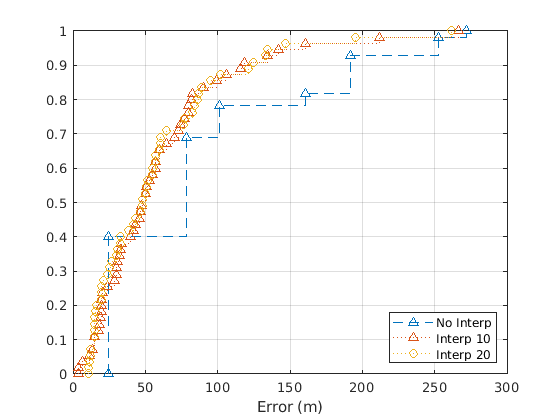

% Plotting
figure(); hold on; grid on;
stairs(mp_x, mp_y, '--^');
stairs(mp_5_x, mp_5_y, ':^');
stairs(mp_20_x, mp_20_y, ':o');
legend('No Interp', 'Interp 10','Interp 20', 'Location','southeast');
xlabel('Error (m)');
box on;

### Linear vs  Non-Linear

% Interp 20
load('/home/ygglc/desktop/phd/research/localization/core/localization-tdoa/matlab/sensys/zurich/mdphase_i20_c1_l1.mat')
dphase_1_1_1.lls = error_lls;
dphase_1_1_1.nlls = error_nlls;
[dphase_1_1_1.F_lls, dphase_1_1_1.X_lls] = ecdf(error_lls);
[dphase_1_1_1.F_nlls, dphase_1_1_1.X_nlls] = ecdf(error_nlls);

offset = mean(nlls(:,1:2),1) - uetliberg(1:2);
nlls_corr = nlls(:,1:2) - offset;
error_nlls_corr = distance(nlls_corr(:,1)',nlls_corr(:,2)',uetliberg(1), uetliberg(2), ell);
[mp_nl_y, mp_nl_x] = ecdf(error_nlls_corr);

offset = mean(lls(:,1:2),1) - uetliberg(1:2);
lls_corr = lls(:,1:2) - offset;
error_lls_corr = distance(lls_corr(:,1)',lls_corr(:,2)',uetliberg(1), uetliberg(2), ell);
[mp_l_y, mp_l_x] = ecdf(error_lls_corr);

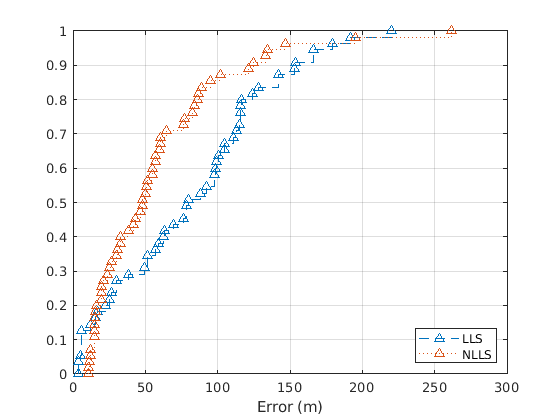

% Plotting
figure(); hold on; grid on;
stairs(mp_l_x, mp_l_y, '--^');
stairs(mp_nl_x, mp_nl_y, ':^');
legend('LLS', 'NLLS', 'Location','southeast');
xlabel('Error (m)');
box on;